data = 10×9 table
       Rodzaj       IPL1     IPL2     IPL3     IPN    ISL1    ISL2    ISL3    IS0
    ____________    _____    _____    _____    ___    ____    ____    ____    ___

    {'L1-N'    }    0.598    0.356    0.306     0     1.2     0.7     0.6      0 
    {'L2-N'    }    0.307      0.6    0.355     0     0.6     1.2     0.7      0 
    {'L3-N'    }     0.36    0.309    0.605     0     0.7     0.6     1.3      0 
    {'L1-L2-N' }    1.226    1.404    0.262     0     2.6     2.9     0.5      0 
    {'L1-L3-N' }      1.4    0.262    1.223     0     2.9     0.5     2.6      0 
    {'L2-L3-N' }    0.264    1.216    1.391     0     0.6     2.6     2.9      0 
    {'L1-L2'   }   

  1×9 table

     Rodzaj     IPL1     IPL2     IPL3     IPN    ISL1    ISL2    ISL3    IS0
    ________    _____    _____    _____    ___    ____    ____    ____    ___

    {'L1-N'}    0.598    0.356    0.306     0     1.2     0.7     0.6      0 

  1×9 table

     Rodzaj     IPL1     IPL2    IPL3     IPN    ISL1    ISL2    ISL3    IS0
    ________    _____    ____

Kąt prądu neutralnego Ipn: 0 stopni


Kąt prądu neutralnego Ipn: 0 stopni


Ipl1: 0.598


Ipl2: -0.178-0.30831i


Ipl3: -0.153+0.265i


Ipn: 0


Isl1: -1.2


Isl2: 0.35+0.60622i


Isl3: 0.3-0.51962i


Is0: 0


Ipl1: 0.598, Ipl2: -0.178-0.30831i, Ipl3: -0.153+0.265i, Ipn: 0, Isl1: -1.2, Isl2: 0.35+0.60622i, Isl3: 0.3-0.51962i, Is0: 0


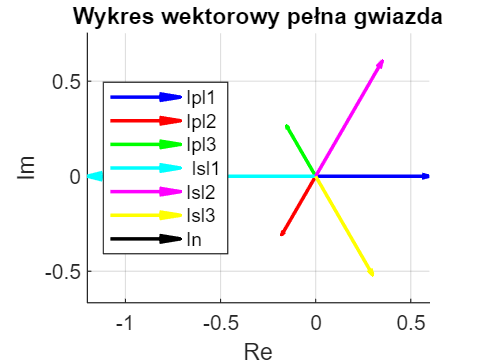

[filename, pathname] = uigetfile({'*.csv', 'Pliki CSV (*.csv)'; '*.txt', 'Pliki tekstowe (*.txt)'}, 'Wybierz plik CSV');
        if ischar(filename) && ischar(pathname)
            % Wybrane plik zostanie otwarty i przetworzony
            fullFileName = fullfile(pathname, filename);
            % Tutaj możesz dodać kod do obsługi wybranego pliku CSV
            % Wybrane plik zostanie otwarty i przetworzony
     
        % Wczytaj dane z pliku CSV (przykładowo używając funkcji csvread lub readtable)
        % Przykładowy kod załadowania danych (w zależności od formatu pliku CSV):
 % Jeśli używasz tabeli
        data=readtable(fullFileName); % Jeśli używasz macierzy
        display(data);

      % Przypisz dane z każdego wiersza do odpowiednich zmiennych
    
      for i = 1:size(data, 1)
         daneWiersza{i} = data(i, :);
         display(daneWiersza{i});
      end
      % Odczytaj dane z pliku CSV (zakładam, że masz już wczytane dane do tabeli 'data')


% Załóżmy, że masz tabelę 'data' i chcesz odczytać wartość z wiersza 3 i kolumny 2 (indeksowane od 1).
%...
%switch jakiś tam, użytkownik wybrał wcześniej dany ukłąd

wiersz = 1;%tu uzytkownik wybiera wiersz
Ipl1 = data{wiersz, 2};
Ipl2 = data{wiersz, 3}* exp(1)^(deg2rad(-120) * 1i);
Ipl3 = data{wiersz, 4}* exp(1)^(deg2rad(120) * 1i);
Ipn = data{wiersz, 5};
Isl1 = -data{wiersz, 6};
Isl2 = -data{wiersz, 7}* exp(1)^(deg2rad(-120) * 1i);
Isl3 = -data{wiersz, 8}* exp(1)^(deg2rad(120) * 1i);
Is0 = data{wiersz, 9};
% Obliczenie kąta prądu neutralnego względem sumy prądów fazowych
angle_deg = rad2deg(angle(Ipn));
angle_deg2 = rad2deg(angle(Is0));
% Wyświetlenie kąta
disp(['Kąt prądu neutralnego Ipn: ', num2str(angle_deg), ' stopni']);
disp(['Kąt prądu neutralnego Ipn: ', num2str(angle_deg2), ' stopni']);
disp(['Ipl1: ' num2str(Ipl1)]);
disp(['Ipl2: ' num2str(Ipl2)]);
disp(['Ipl3: ' num2str(Ipl3)]);
disp(['Ipn: ' num2str(Ipn)]);
disp(['Isl1: ' num2str(Isl1)]);
disp(['Isl2: ' num2str(Isl2)]);
disp(['Isl3: ' num2str(Isl3)]);
disp(['Is0: ' num2str(Is0)]);
disp(['Ipl1: ' num2str(Ipl1) ', Ipl2: ' num2str(Ipl2) ', Ipl3: ' num2str(Ipl3) ', Ipn: ' num2str(Ipn) ', Isl1: ' num2str(Isl1) ', Isl2: ' num2str(Isl2) ', Isl3: ' num2str(Isl3) ', Is0: ' num2str(Is0)]);
% Przygotowanie danych do wykresu
Imag = [Ipl1,Ipl2,Ipl3,Isl1,Isl2,Isl3];
Re = real(Imag);
Im = imag(Imag);

% Tworzenie wektorów dla wykresu
figure;
hold on;
quiver(0, 0, Re(1), Im(1), 0, 'b', 'LineWidth', 1.5);
quiver(0, 0, Re(2), Im(2), 0, 'r', 'LineWidth', 1.5);
quiver(0, 0, Re(3), Im(3), 0, 'g', 'LineWidth', 1.5);
quiver(0, 0, Re(4), Im(4), 0, 'c', 'LineWidth', 1.5);
quiver(0, 0, Re(5), Im(5), 0, 'm', 'LineWidth', 1.5);
quiver(0, 0, Re(6), Im(6), 0, 'y', 'LineWidth', 1.5);
quiver(0, 0, real(Ipn), imag(Ipn), 0, 'k', 'LineWidth', 1.5);
% Legenda
legend('Ipl1', 'Ipl2', 'Ipl3',' Isl1','Isl2','Isl3','In','Location', 'Best');
        % Konfiguracja osi
axis equal;
xlabel('Re');
ylabel('Im');
grid on;
title('Wykres wektorowy pełna gwiazda');
        end